# FUELREGULARIZED

Fit and evaluate regularized linear models of fuel economy.

## Load data

load carEcon

## Make numeric variables out of tabular data (including categoricals)

[X,names] = cattable2mat(carData);
Xtrain = X(idxTrain,:);
Xtest = X(~idxTrain,:);
ytrain = carTrain.FuelEcon;
ytest = carTest.FuelEcon;

## Perform ridge regression on fuel economy

Define a range of the regularization parameter

lambda = 0:200;
b = ridge(ytrain,Xtrain,lambda,0);

View the effect of `lambda` on the coefficients and error

subplot(2,1,1)
plot(lambda,b')
subplot(2,1,2)

Make predictions. The first row of `b` contains the intercept, and the other rows contain the coefficients.

Y = b(1,:) + Xtest*b(2:end,:);

Note `Y` is a matrix (one column for each value of `lambda`)

Need to calculate MSE for each column

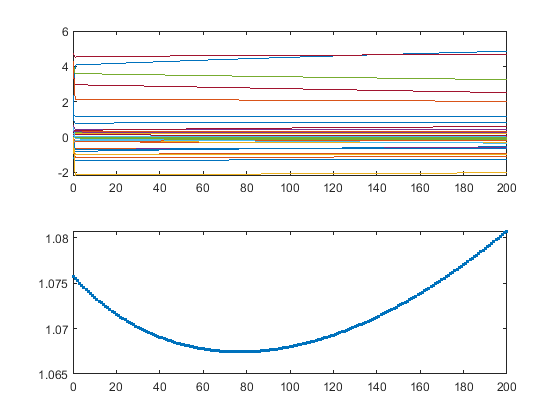

mse = mean((Y - ytest).^2);
plot(lambda,mse,'.-')

Evaluate best fit

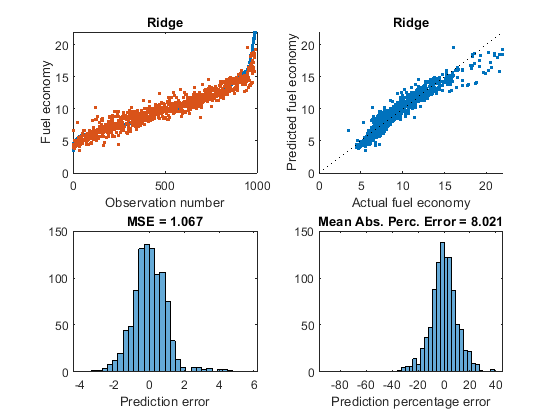

[~,k] = min(mse);
evaluatefit(ytest,Y(:,k),'Ridge')

## Perform lasso regression on fuel economy

Different interpretation of `lambda` (scaling by number of observations)

lambda = lambda/height(carTrain);
[b,fitinfo] = lasso(Xtrain,ytrain,'Lambda',lambda);

View the effect of `lambda` on the coefficients and error

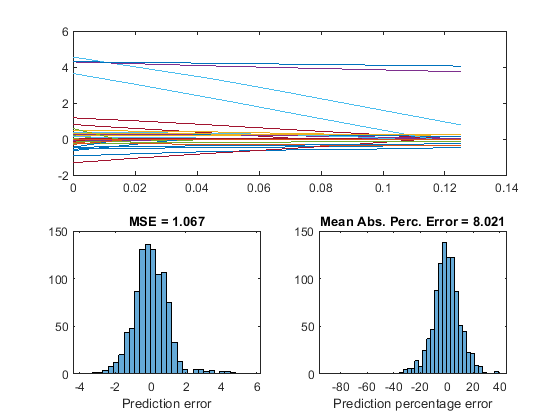

subplot(2,1,1)
plot(lambda,b')

subplot(2,1,2)

The intercept is stored in `fitinfo` (no need to calculate)

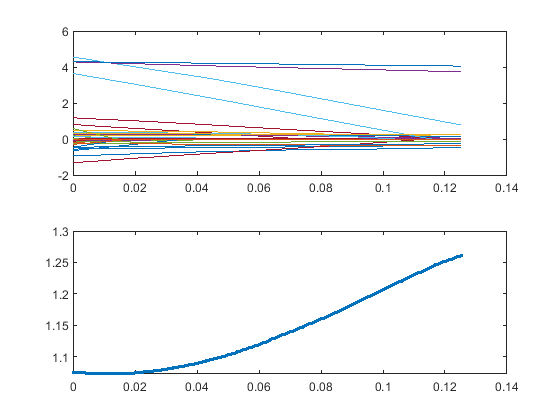

Y = fitinfo.Intercept + Xtest*b;
mse = mean((Y - ytest).^2);
plot(fitinfo.Lambda,mse,'.-')

Evaluate best fit

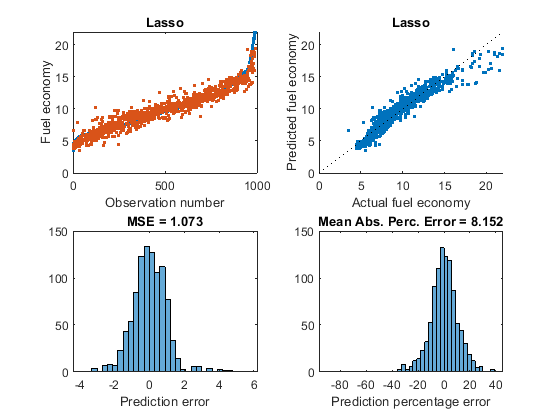

[~,k] = min(mse);
Y = fitinfo.Intercept(k) + Xtest*b(:,k);
evaluatefit(ytest,Y,'Lasso')

## Perform elastic net regression on fuel economy

[b,fitinfo] = lasso(Xtrain,ytrain,'Lambda',lambda,'Alpha',0.6);

View the effect of `lambda` on the coefficients and error

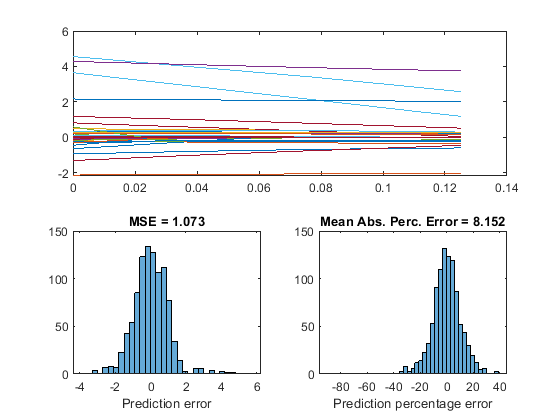

subplot(2,1,1)
plot(lambda,b')

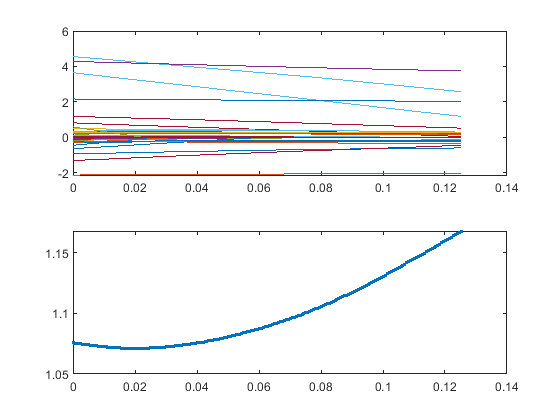

subplot(2,1,2)
Y = fitinfo.Intercept + Xtest*b;
mse = mean((Y - ytest).^2);
plot(fitinfo.Lambda,mse,'.-')

Evaluate best fit

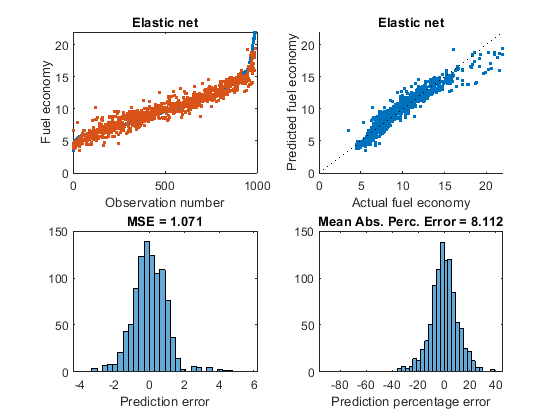

[~,k] = min(mse);
Y = fitinfo.Intercept(k) + Xtest*b(:,k);
evaluatefit(ytest,Y,'Elastic net')